% Error analysis and comparison of orders of convergence
% Felix Rutsch, May 2025

clearvars;



$$ u(x) = \frac{d}{dx}f(x)$$


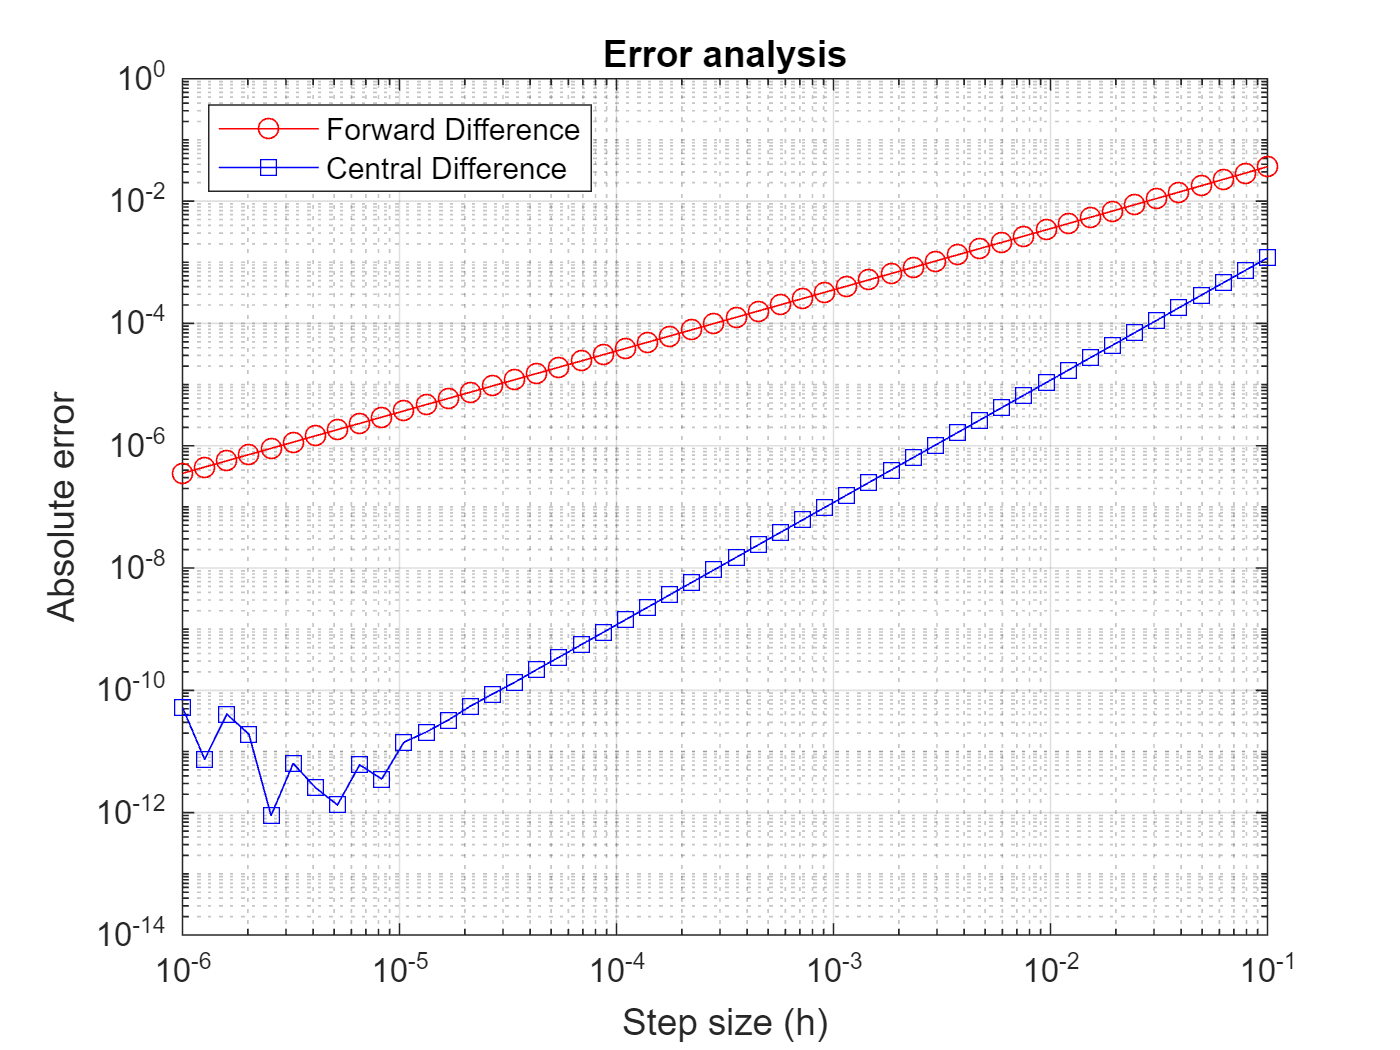


% Differential equation:
% u(x) = df(x)/dx

% Define function and exact solution
f = @(x) sin(x);
u_exact = @(x) cos(x);

% Point at which derivative is evaluated
x0 = pi / 4;

% Range of step sizes
h = logspace(-6, -1, 50); % from 1e-6 to 1e-1: 50 points

% Preallocate error arrays
error_forward = zeros(size(h));
error_central = zeros(size(h));

for i = 1:length(h)
    hi = h(i);
    
    % Forward finite difference
    u_forward = (f(x0 + hi) - f(x0)) / hi;
    
    % Central finite difference
    u_central = (f(x0 + hi) - f(x0 - hi)) / (2 * hi);
    
    % Compute absolute errors
    error_forward(i) = abs(u_forward - u_exact(x0));
    error_central(i) = abs(u_central - u_exact(x0));
end

%% Plotting error vs step size
loglog(h, error_forward, 'r-o', 'DisplayName', 'Forward Difference');
hold on;
loglog(h, error_central, 'b-s', 'DisplayName', 'Central Difference');
grid on;
xlabel('Step size (h)');
ylabel('Absolute error');
title('Error analysis');
legend('Location', 'northwest');


% Estimate slopes (order of accuracy)


$$p = \frac{\log(E(h_1))-\log(E(h_2))}{\log(h_1)-\log(h_2)}$$


p_forward = ( log(error_forward(20)/error_forward(30)) )/( log(h(20)/h(30)) )

p_forward = 1.0001

p_central = ( log(error_central(20)/error_central(30)) )/( log(h(20)/h(30)) )

p_central = 2.0000